The original equation is: 


$$\frac{d^2 \phi_n }{{\mathrm{dx}}^2 }-\left({\mathrm{Kx}}^2 -\epsilon_n \right)\phi_n =0$$


This is the substituion of the equation, and it's: 


$$y_1 =\phi_n \left(x\right)$$



$$y_2 ={\phi_n }^{\prime } \left(x\right)$$


The boundary condition on the left hand side is underdetermined by a parameter, say $A$


$${y_1 =\;\phi }_n \left(-L\right)=A$$



$$y_2 =\;{\phi_n }^{\prime } \left(-L\right)=A\sqrt{L^2 -\epsilon }$$


The solution multiled by any constant is still good, hence, for any constant $A$ chosen, it will be a good solution, I think that is why we normalizing the function at the end. 

The boundary value on the right hand side that we are trying to solve for is: 


$${\phi_n }^{\prime } \left(L\right)+\sqrt{\;L^2 -\epsilon }\phi_n \left(L\right)=0$$


What are we visualizing? 

Here are some of the suspects, in increasing magnitude of epsilons: 

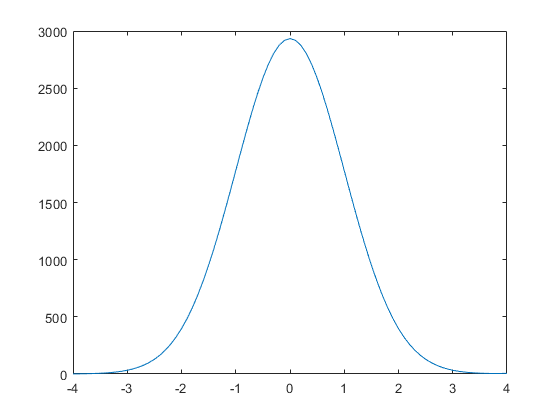

A = 1; L = 4; Epsilon = 0.99983;
y0 = [A, A*sqrt(L^2 - Epsilon)];
Tspan = -L: 0.1: L;

[Xs, Ys] = ode45(@(t, y) Quantum(t, y, Epsilon), Tspan, y0);
plot(Xs, Ys(:, 1));


Ys(end, 2) + sqrt(L^2 - Epsilon)*Ys(end, 1)

ans =   35.658747616019923


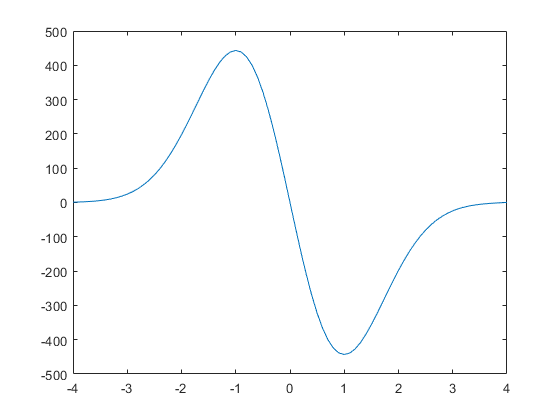

A = 1; L = 4; Epsilon = 2.9995;
y0 = [A, A*sqrt(L^2 - Epsilon)];
Tspan = -L: 0.1: L;

[Xs, Ys] = ode45(@(t, y) Quantum(t, y, Epsilon), Tspan, y0);
plot(Xs, Ys(:, 1));


Ys(end, 2) + sqrt(L^2 - Epsilon)*Ys(end, 1)

ans =    8.490036842241992


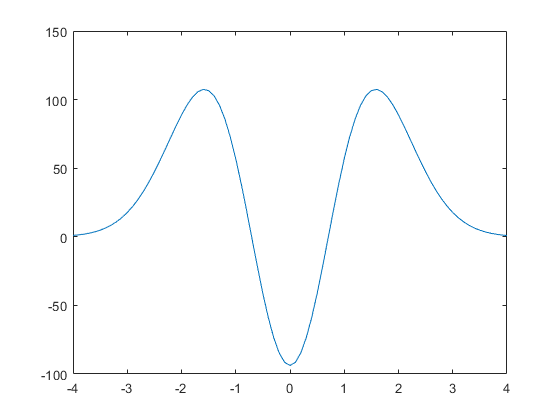

A = 1; L = 4; Epsilon = 4.9993;
y0 = [A, A*sqrt(L^2 - Epsilon)];
Tspan = -L: 0.1: L;

[Xs, Ys] = ode45(@(t, y) Quantum(t, y, Epsilon), Tspan, y0);
plot(Xs, Ys(:, 1));

The modes appears in order, they are not far apart from each other, and they seems to be alternating. 

Therefore, the previous modes will be used as initial conditions to shoot for the next one, but reverse the stepping conditions. 

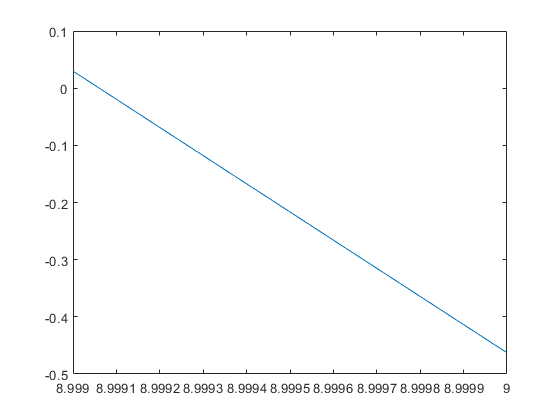

Xlinspace = linspace(8.999, 9, 1000);
plot(Xlinspace, RHSDV(Xlinspace));

Let's plot this functon out. 

Interesting we can solve for the fzero right? 

[x, fval] = fzero(@RHSDV, 9);
x

x =    8.999060571379053


fval

fval =     -8.393286066166183e-14


RHSDV(8.999942335700617)

ans =   -0.434447879067021
